# Offline RL for Goal-Based Wealth Management

This demo is to build an offline agent for goal-based wealth management (GBWM) using the historical daily dataset. To run this example, it is required to install reinforcement learning toolbox and financial toolbox

clear
clc
rng(1000,"twister"); % for reproducibility

## Parameter Settings

Specify the initial wealth and the target wealth at the end of the investment horizon.

initialWealth   = 100000;    % initial wealth
goalWealth      = 102000;    % target wealth at horizon
horizonPeriods  = 60;         % number of rebalancing periods in each episode (e.g., months)
contribution    = 0;        % fixed contribution per period (can be 0)
rebalanceStep   = calmonths(1); % assumed price frequency (monthly)

% --- Offline dataset generation ---
numEpisodes     = 400;        % how many episodes to create from history
numActions      = 15;         % number of efficient frontier points (discrete actions)
logsFolder      = fullfile("experiments", "logs", "week2_baseline");  % folder to save episodes

% --- Agent / training ---
hiddenUnits     = 32;         % critic MLP width
maxEpochs       = 100;        % offline training epochs
stepsPerEpoch   = 400;       % gradient steps per epoch
miniBatchSize   = 256;        % mini-batch size when training from data
discountFactor  = 0.995;      % RL discount

## Compute historical returns and Define action set

% Load the dataset
pricesTT = readtable("data/SimulatedData.xlsx");
assetNames = pricesTT.Properties.VariableNames;
% Compute (continuous) returns timetable from prices
retTT = price2ret(pricesTT,'Method','continuous');
retTT

retTT = 504×5 table
    Tick    Interval      Stock1        Stock2        Stock3   
    ____    ________    __________    __________    ___________

      2        1         0.0055834      0.011756       0.011244
      3        1          0.013994     0.0053284     -0.0020941
      4        1        -0.0075215    -0.0013273      -0.032291
      5        1          0.021243      0.011179     -0.0064772
      6        1        -0.0068362     0.0090134     -0.0079277
      7        1          0.022347       0.03128       0.030182
      8        1          0.011898      -0.02419      -0.019614
      9        1         0.0020176    -0.0099112       -0.02898
     10        1         0.0074773     -0.011422    -0.00076639
     11        1          0.013118      0.010926     -0.0096653
     12        1        -0.0051303     -0

Mean and Covariance of the returns from the historical asset prices

% Convert returns to numeric matrix aligned with time
trainingRange = 252;
R_sub = retTT{1:trainingRange, 3:end};           % T-1 x Nassets
% Sample mean & covariance from history (for efficient frontier actions)
mu    = mean(R_sub,1)';        % Nassets x 1
Sigma = cov(R_sub);            % Nassets x Nassets

% Build efficient frontier actions using Portfolio object
% (long-only, fully-invested, default constraints)
p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p); %long only, fully-invested
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);  % Nassets x numActions

Plot the efficient frontier using `plotFrontier`.

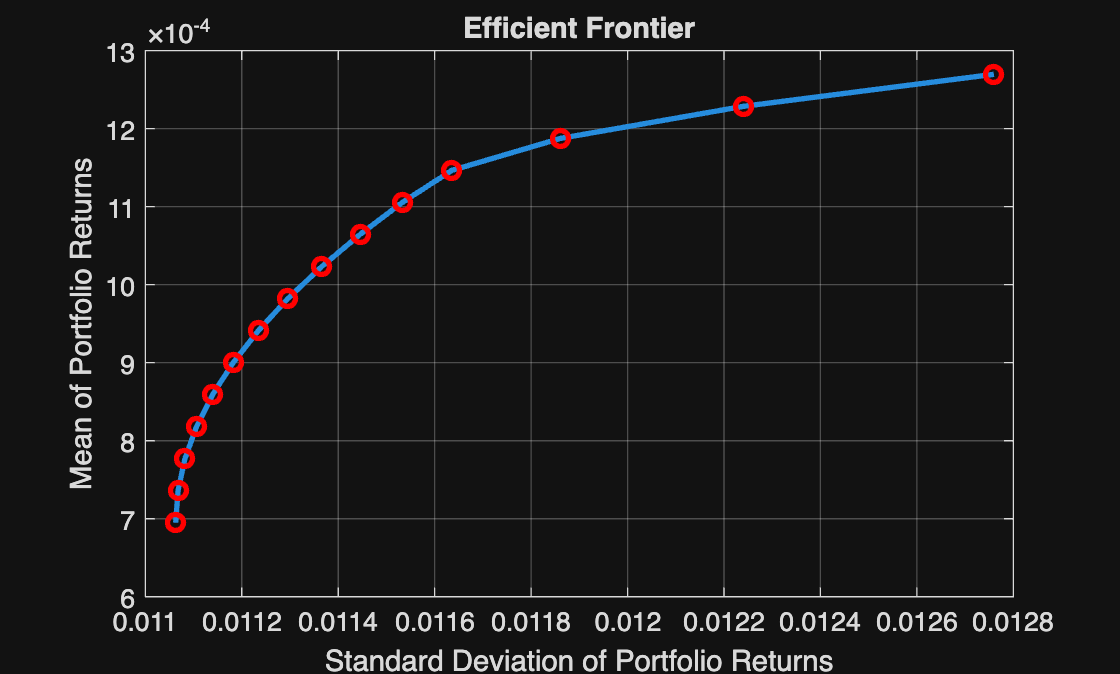

figure
[prsk, pret] = plotFrontier(p,numActions);
hold on
scatter(prsk, pret,"red","o","LineWidth",2);
hold off

## Build offline episodes from historical returns

% We slide episode windows over history. Each episode has 'horizonPeriods' returns.
% At each step, pick a behavior action index uniformly at random (replace if you have logged actions).
if ~isfolder(logsFolder); mkdir(logsFolder); end

% Utility: normalize wealth and time to observation vector
normalizeWealth = @(w) min(w/goalWealth, 5);  % clip for stability
timeFrac        = @(t) t / horizonPeriods;

episodeCount = 0;
startIdx = 1;

while episodeCount < numEpisodes && (startIdx + horizonPeriods - 1) <= size(R_sub,1)
    episodeCount = episodeCount + 1;
    expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
        "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

    wealth = initialWealth;
    for t = 1:horizonPeriods
        % Current observation: [normalized wealth, timePeriod]
        obs  = [normalizeWealth(wealth); timeFrac(t)];
        % Choose behavior action index (1..numActions). Replace with your logger if available.
        aIdx = randi(numActions);
        w    = W_frontier(:, aIdx);     % weights for this action

        % Realized portfolio return at current period from historical returns
        r_tp1 = R_sub(startIdx + t - 1, :) * w;  % scalar

        % Apply contribution & growth to get next wealth
        wealthNext = (wealth + contribution) * (1 + r_tp1);

        % Sparse reward: only at final step, 1 if goal reached, else 0 — as in GBWM example.
        reward = double( (t == horizonPeriods) && (wealthNext >= goalWealth) );

        % Next observation
        nextObs = [normalizeWealth(wealthNext); timeFrac(min(t+1,horizonPeriods))];

        % Done only at terminal step
        isDone = (t == horizonPeriods);

        % Store transition in the episode struct (trainFromData expects cell-wrapped channels)
        expStruct(t).Observation     = {obs};
        expStruct(t).Action          = {aIdx};
        expStruct(t).Reward          = reward;
        expStruct(t).NextObservation = {nextObs};
        expStruct(t).IsDone          = isDone;

        wealth = wealthNext;
    end

    % Save episode to MAT file (trainFromData example format)
    epFile = fullfile(logsFolder, sprintf("loggedData%03d.mat", episodeCount));
    exp = expStruct;
    save(epFile, "exp");
    startIdx = startIdx + floor(horizonPeriods/2); % slide window with overlap
end

fprintf("Saved %d offline episodes to '%s'.\n", episodeCount, logsFolder);

Saved 7 offline episodes to 'experiments/logs/week2_baseline'.


## Create FileDatastore & ReadFcn

% Read function must return the episode struct array with fields:
% Observation, Action, Reward, NextObservation, IsDone.  [2](https://www.mathworks.com/help/reinforcement-learning/ref/trainfromdata.html)
myReadFcn = @(fname) load(fname, "exp").exp;

fds = fileDatastore(logsFolder, "ReadFcn", myReadFcn, "FileExtensions", ".mat");  

## Build DQN agent for GBWM

The purpose of the agent is to select actions that are sent to the environment. The agent then receives the new observations from the environment and the reward generated by the submitted actions. The goal of RL workflow is to train the agent to select the best possible actions to maximize the reward function by the end of the investment horizon.

Observation: 2 features: normalized wealth, and time Period

obsInfo = rlNumericSpec([2 1], Name="GBWMObservation");

actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

% Critic network: maps observation -> Q-values for all actions
criticLG = layerGraph([
    featureInputLayer(obsInfo.Dimension(1), Name="state")
    fullyConnectedLayer(hiddenUnits)
    reluLayer
    fullyConnectedLayer(hiddenUnits)
    reluLayer
    fullyConnectedLayer(numActions, Name="Qout")
    ]);

criticNet = dlnetwork(criticLG);
critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

% DQN agent options
agentOpts = rlDQNAgentOptions( ...
    DiscountFactor=discountFactor, ...
    ExperienceBufferLength=1e6, ...
    MiniBatchSize=miniBatchSize, ...
    TargetUpdateMethod="periodic", ...
    TargetUpdateFrequency=4, ...
    UseDoubleDQN=true...
    );
agentOpts.CriticOptimizerOptions.LearnRate=5e-4;
agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
agent = rlDQNAgent(critic, agentOpts);

## Train offline from Historical Dataset

doTraining = true;
if doTraining
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "training-progress", ...
        Verbose          = true ...
        );
    tfdStats = trainFromData(agent, fds, tfdOpts);  % offline training
    save("experiments/logs/week2_baseline/TrainedAgent.mat", "agent");
else
    load("experiments/logs/week2_baseline/TrainedAgent.mat");
end

Epoch:    1/ 100 | Step Count:    400/40000 | Q Value:   1.5523 | Num experiences added:  420
Epoch:    2/ 100 | Step Count:    800/40000 | Q Value:   3.5052 | Num experiences added:    0
Epoch:    3/ 100 | Step Count:   1200/40000 | Q Value:   2.3327 | Num experiences added:    0
Epoch:    4/ 100 | Step Count:   1600/40000 | Q Value:   1.2835 | Num experiences added:    0
Epoch:    5/ 100 | Step Count:   2000/40000 | Q Value:   1.2227 | Num experiences added:    0
Epoch:    6/ 100 | Step Count:   2400/40000 | Q Value:   1.3474 | Num experiences added:    0
Epoch:    7/ 100 | Step Count:   2800/40000 | Q Value:   1.0127 | Num experiences added:    0
Epoch:    8/ 100 | Step Count:   3200/40000 | Q Value:   0.8556 | Num experiences added:    0
Epoch:    9/ 100 | Step Count:   3600/40000 | Q Value:   0.7707 | Num experiences added:    0
Epoch:   10/ 100 | Step Count:   4000/40000 | Q Value:   0.7426 | Num experiences added:    0
Epoch:   11/ 100 | Step Count:   4400/40000 | Q Value:   0.8

## Quick evaluation on a hold-out window (Optional)

Simulate one episode using greedy actions from the trained agent

% load different dataset
filename = 'data/SimulatedData.xlsx';
newReturn = inputTestData(filename);
holdOutStart = trainingRange+1;  % next unseen window
R = newReturn{:, 3:end};
if (holdOutStart + horizonPeriods - 1) <= size(R,1)
    wealth(1)= initialWealth;
    success = false;
    for t = 1:horizonPeriods
        obs = { [normalizeWealth(wealth(t)); timeFrac(t)] };
        aGreedy = agent.getAction(obs);  % greedy action index (epsilon set to 0 during evaluation)
        w  = W_frontier(:, aGreedy{1});
        r_tp1 = R(holdOutStart + t - 1, :) * w;
        wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
    end
    success = (wealth(end) >= goalWealth);
    fprintf("Hold-out episode success: %d (terminal wealth = %.2f)\n", success, wealth(end));
end

Hold-out episode success: 1 (terminal wealth = 111242.22)


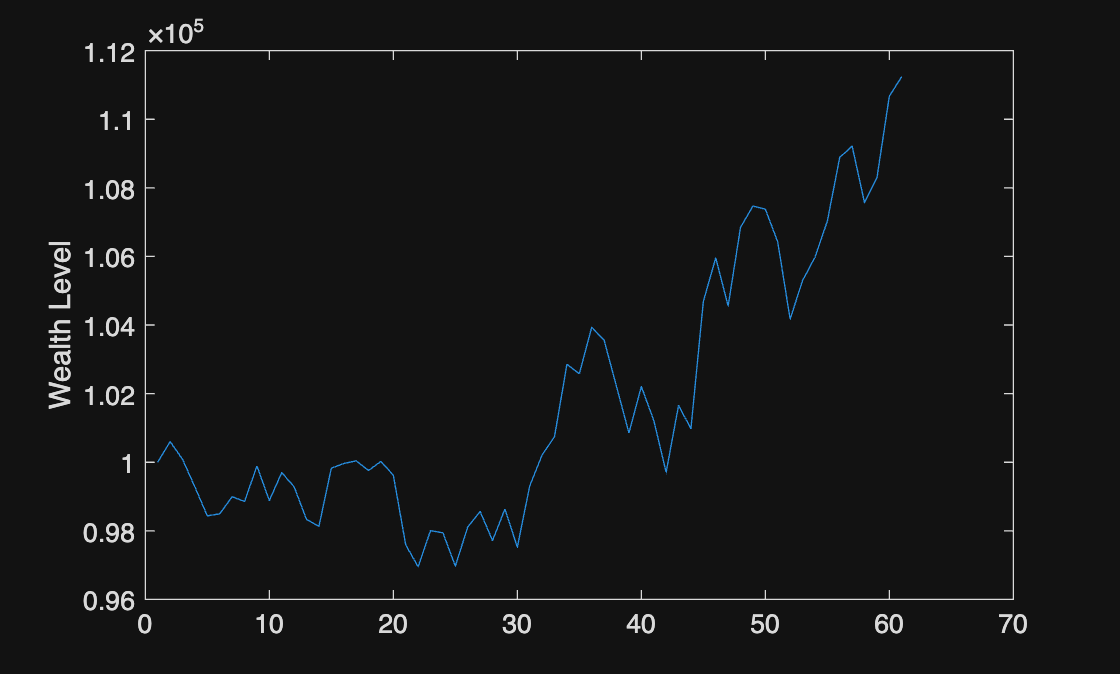

figure
plot(wealth)
ylabel('Wealth Level')

## Local Functions

function Return = inputTestData(filename)
pricesTT = readtable(filename,'VariableNamingRule','preserve');
% Compute (continuous) returns timetable from prices
Return = price2ret(pricesTT,'Method','continuous');
end